Let's begin

close all
clear all

## Read all the files

% -----------------------------------------
% read in the data of dissolved oxygen
% -----------------------------------------
filename = 'Dissolved Oxygen sensor data.TXT';
varNames = {'unix_timestamp', 'UTC_date_time', 'EU_date_time', 'battery', 'temperature', 'dissolved_oxygen', 'dissolved_oxygen_saturation', 'Q'};
varTypes = {'uint32','char','char','double','double','double','double','double'}; 
delimiter = ',';
dataStartLine = 10;
extraColRule = 'ignore';
opts = delimitedTextImportOptions('VariableNames',varNames,...
                                'VariableTypes',varTypes,...
                                'Delimiter',delimiter,...
                                'DataLines', dataStartLine,...
                                'MissingRule', 'omitrow',...
                                'ExtraColumnsRule',extraColRule); 
DOSDtmp = readtable(filename,opts);

% CONVERT datetime columns
DOSDtmp.EU_date_time = datetime(DOSDtmp.EU_date_time, 'Inputformat', 'yyyy-MM-dd HH:mm:ss');
DOSD = removevars(DOSDtmp,{'unix_timestamp', 'UTC_date_time', 'EU_date_time', 'battery'});
DOSD.date_time = datetime(DOSDtmp.EU_date_time, 'Inputformat', 'yyyy-MM-dd HH:mm:ss');
clear DOSDtmp

% -----------------------------------------
% read in the data of wind Codevigo
% -----------------------------------------
filename = 'wind175.txt';
varNames = {'date_time', 'wind'};
varTypes = {'char','double'}; 
delimiter = '	';
dataStartLine = 1;
extraColRule = 'ignore';
opts = delimitedTextImportOptions('VariableNames',varNames,...
                                'VariableTypes',varTypes,...
                                'Delimiter',delimiter,...
                                'DataLines', dataStartLine,...
                                'MissingRule', 'omitrow',...
                                'ExtraColumnsRule',extraColRule); 
WIND = readtable(filename,opts);

% CONVERT datetime columns
WIND.date_time = datetime(WIND.date_time, 'Inputformat', 'MM/dd/yy');
clear Wtmp

% -----------------------------------------
% read in the data of tide level
% -----------------------------------------
filename = 'tide level.txt';
varNames = {'date', 'time', 'water_level'};
varTypes = {'char','char','double'}; 
delimiter = ';';
dataStartLine = 2;
extraColRule = 'ignore';
opts = delimitedTextImportOptions('VariableNames',varNames,...
                                'VariableTypes',varTypes,...
                                'Delimiter',delimiter,...
                                'DataLines', dataStartLine,...
                                'MissingRule', 'omitrow',...
                                'ExtraColumnsRule',extraColRule); 
TIDEtmp = readtable(filename,opts);
% CONVERT datetime column
TIDE = removevars(TIDEtmp, {'date','time'});
TIDE.date_time = datetime(append(TIDEtmp.date, ' ', TIDEtmp.time), 'Inputformat', 'dd/MM/yyyy HH:mm');
clear TIDEtmp

% -----------------------------------------
% read in the data of rain (Chioggia Sant'Anna)
% -----------------------------------------
filename = 'IntVari110609.txt';
varNames = {'place', 'title', 'date', 'time', 'rain'};
varTypes = {'char','char','char','char','double'}; 
selvarNames = {'title','date', 'time', 'rain'};
delimiter = ';';
dataStartLine = 2;
opts = delimitedTextImportOptions('VariableNames',varNames,...
                                'VariableTypes',varTypes,...
                                'Delimiter',delimiter,...
                                'DataLines', dataStartLine,...
                                'MissingRule', 'omitrow',...
                                'ExtraColumnsRule',extraColRule); 
CSARtmp = readtable(filename,opts);
% CONVERT datetime column
CSAR = removevars(CSARtmp,{'date','time'});
CSAR.date_time = datetime(append(CSARtmp.date, ' ', CSARtmp.time), 'Inputformat', 'dd/MM/yyyy HH:mm');
clear CSARtmp

idx_rain = CSAR.title == "Precipitazione (mm)";
idx_rad = CSAR.title == "Radiazione solare globale (W/m2)";
idx_temp = CSAR.title == "Temperatura aria a 2m (°C)";
idx_hum = CSAR.title == "Umidità relativa a 2m (%)";

% -----------------------------------------
% read in the data of rain (Codevigo - Ca' di Mezzo)
% -----------------------------------------
filename = 'IntVari110609.txt';
opts = delimitedTextImportOptions('VariableNames',varNames,...
                                'VariableTypes',varTypes,...
                                'SelectedVariableNames', selvarNames,...
                                'Delimiter',delimiter,...
                                'DataLines', dataStartLine,...
                                'MissingRule', 'omitrow',...
                                'ExtraColumnsRule',extraColRule); 
CCMRtmp = readtable(filename,opts);
% CONVERT datetime column
CCMR = removevars(CCMRtmp,{'date','time'});
CCMR.date_time = datetime(append(CCMRtmp.date, ' ', CCMRtmp.time), 'Inputformat', 'dd/MM/yyyy HH:mm');
clear CCMRtmp

idx_rain = CCMR.title == "Precipitazione (mm)";
idx_rad = CCMR.title == "Radiazione solare globale (W/m2)";
idx_temp = CCMR.title == "Temperatura aria a 2m (°C)";
idx_hum = CCMR.title == "Umidità relativa a 2m (%)";

% Average the 2 rain sensors

CCMR.rain = (CCMR.rain + CSAR.rain)/2;

rain = CCMR(idx_rain,:).rain;
radiation = CCMR(idx_rad,:).rain;
airT = CCMR(idx_temp,:).rain;
humidity = CCMR(idx_hum,:).rain;
date_time = CCMR(idx_rain,:).date_time;
Rain = table(date_time,rain);
Rain = rmmissing(Rain);
date_time = CCMR(idx_rad,:).date_time;
RAH = table(date_time,radiation,airT,humidity);
RAH = rmmissing(RAH);

clear rain radiation airT humidity date_time idx_hum idx_rad idx_rain idx_temp opts selvarNames varNames varTypes
clear filename extraColRule delimiter dataStartLine CCMR CSAR

% -----------------------------------------
% read in the data of Samanet 2020 sensor 9
% -----------------------------------------
[SD2020num, SD2020date_time] = xlsread('Samanet data 2020.xlsx','Ve-9');
SD2020 = array2table(SD2020num,...
        'VariableNames',{'pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'});
SD2020.date_time = datetime(SD2020date_time(2:end,1), 'InputFormat', 'dd/MM/yyyy HH');
clear SD2020date_time SD2020num

% -----------------------------------------
% read in the data of Samanet 2021 sensor 9
% -----------------------------------------
[SD2021num, SD2021date_time] = xlsread('Samanet data 2021.xlsx','Ve-9');
SD2021 = array2table(SD2021num,...
        'VariableNames',{'pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'});
SD2021.date_time = datetime(SD2021date_time(2:end,1), 'InputFormat', 'dd/MM/yyyy HH');

SD = [SD2020; SD2021];

clear SD2020 SD2021 SD2021num SD2021date_time 

SD.pressure = SD.pressure.*73.5510312;

% -----------------------------------------
% read in the data of Samanet 2020 sensor 1
% -----------------------------------------
[SD2020num, SD2020date_time] = xlsread('Samanet data 2020.xlsx','Ve-1');
SD2020 = array2table(SD2020num,...
        'VariableNames',{'pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'});
SD2020.date_time = datetime(SD2020date_time(2:end,1), 'InputFormat', 'dd/MM/yyyy HH');
clear SD2020date_time SD2020num

% -----------------------------------------
% read in the data of Samanet 2021 sensor 1
% -----------------------------------------
[SD2021num, SD2021date_time] = xlsread('Samanet data 2021.xlsx','Ve-1');
SD2021 = array2table(SD2021num,...
        'VariableNames',{'pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'});
SD2021.date_time = datetime(SD2021date_time(2:end,1), 'InputFormat', 'dd/MM/yyyy HH');

SD1 = [SD2020; SD2021];

clear SD2020 SD2021 SD2021num SD2021date_time 

SD1.pressure = SD1.pressure.*73.5510312;

% remove NaNs
SD1 = rmmissing(SD1);

% -----------------------------------------
% read in the data of Samanet 2020 sensor 6
% -----------------------------------------
[SD2020num, SD2020date_time] = xlsread('Samanet data 2020.xlsx','Ve-6');
SD2020 = array2table(SD2020num,...
        'VariableNames',{'pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'});
SD2020.date_time = datetime(SD2020date_time(2:end,1), 'InputFormat', 'dd/MM/yyyy HH');
clear SD2020date_time SD2020num

% -----------------------------------------
% read in the data of Samanet 2021 sensor 6
% -----------------------------------------
[SD2021num, SD2021date_time] = xlsread('Samanet data 2021.xlsx','Ve-6');
SD2021 = array2table(SD2021num,...
        'VariableNames',{'pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'});
SD2021.date_time = datetime(SD2021date_time(2:end,1), 'InputFormat', 'dd/MM/yyyy HH');

SD6 = [SD2020; SD2021];

clear SD2020 SD2021 SD2021num SD2021date_time 
% convert pressure 
SD6.pressure = SD6.pressure.*73.5510312;

% remove NaNs
SD6 = rmmissing(SD6);

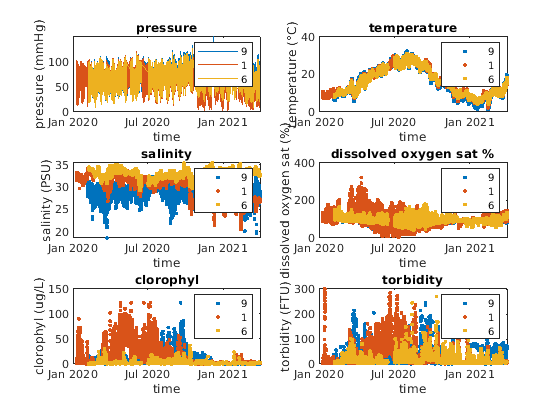

figure
subplot(3,2,1)
plot(SD.date_time, SD.pressure, '-', SD1.date_time, SD1.pressure,'-', SD6.date_time, SD6.pressure,'-')
xlabel('time')
ylabel('pressure (mmHg)')
h1 = legend('9','1','6');
title('pressure')
subplot(3,2,2)
plot(SD.date_time, SD.temperature, '.',SD1.date_time, SD1.temperature, '.',SD6.date_time, SD6.temperature, '.')
xlabel('time')
ylabel('temperature (°C)')
h1 = legend('9','1','6');
title('temperature')
subplot(3,2,3)
plot(SD.date_time, SD.salinity, '.',SD1.date_time, SD1.salinity, '.',SD6.date_time, SD6.salinity, '.')
xlabel('time')
ylabel('salinity (PSU)')
h1 = legend('9','1','6');
title('salinity')
subplot(3,2,4)
plot(SD.date_time, SD.dissolved_oxygen, '.',SD1.date_time, SD1.dissolved_oxygen, '.',SD6.date_time, SD6.dissolved_oxygen, '.')
xlabel('time')
ylabel('dissolved oxygen sat (%)')
h1 = legend('9','1','6');
title('dissolved oxygen sat %')
subplot(3,2,5)
plot(SD.date_time, SD.clorophyl, '.',SD1.date_time, SD1.clorophyl, '.',SD6.date_time, SD6.clorophyl, '.')
xlabel('time')
ylabel('clorophyl (ug/L)')
h1 = legend('9','1','6');
title('clorophyl')
subplot(3,2,6)
plot(SD.date_time, SD.torbidity, '.',SD1.date_time, SD1.torbidity, '.',SD6.date_time, SD6.torbidity, '.')
xlabel('time')
ylabel('torbidity (FTU)')
h1 = legend('9','1','6');
title('torbidity')
savefig('3sensorsSamanet.fig')

%%% INTERPOLATIONS %%%

tobs = days(DOSD.date_time-DOSD.date_time(1)); %day
tobs_h = days(TIDE.date_time-DOSD.date_time(1)); %day
tobs_R = days(RAH.date_time-DOSD.date_time(1)); %day
tobs_ws = days(WIND.date_time-DOSD.date_time(1)); %day

% step
tstep = (tobs(2)-tobs(1));

global tspan
tspan = [0:tstep:tobs(end)]; %day

% Sensor 9
tobs_sd9 = days(SD.date_time-DOSD.date_time(1)); %day
tmp = zeros(length(tspan),6);
for i = 1:6
    tmp(:,i) = interp1(tobs_sd9, table2array(SD(:,i)), tspan);
end
SD = table(tspan.',tmp(:,1), tmp(:,2), tmp(:,3), tmp(:,4), tmp(:,5), tmp(:,6));
SD.Properties.VariableNames = {'date_time','pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'};
idx_nan = zeros(length(tspan),6);
for j = 1:6
    idx_nan(:,j) = isnan(table2array(SD(:,j+1)));
end
clear tobs_sd9 tmp

% Sensor 1
tobs_sd1 = days(SD1.date_time-DOSD.date_time(1)); %day
tmp = zeros(length(tspan),6);
for i = 1:6
    tmp(:,i) = interp1(tobs_sd1, table2array(SD1(:,i)), tspan);
end
SD1 = table(tspan.',tmp(:,1), tmp(:,2), tmp(:,3), tmp(:,4), tmp(:,5), tmp(:,6));
SD1.Properties.VariableNames = {'date_time','pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'};
clear tobs_sd1 tmp

% Sensor 6
tobs_sd6 = days(SD6.date_time-DOSD.date_time(1)); %day
tmp = zeros(length(tspan),6);
for i = 1:6
    tmp(:,i) = interp1(tobs_sd6, table2array(SD6(:,i)), tspan);
end
SD6 = table(tspan.',tmp(:,1), tmp(:,2), tmp(:,3), tmp(:,4), tmp(:,5), tmp(:,6));
SD6.Properties.VariableNames = {'date_time','pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'};
clear tobs_sd6 tmp


% ----------------------------
% Weighted average of samanet sensors
% ----------------------------
idx_nan = logical(idx_nan);
tmp = zeros(length(tspan),6);
normaliz = 1.0/(1.0/6.2+2.0/19.0);
for i = 1:6
    tmp(:,i) = (1/6.2 * table2array(SD(:,i+1)) + 1.0/19 * table2array(SD6(:,i+1)) + 1.0/19 * table2array(SD1(:,i+1)))*normaliz;
    tmp(idx_nan(:,i),i) = 0.5*table2array(SD6(idx_nan(:,i),i+1)) + 0.5*table2array(SD1(idx_nan(:,i),i+1));
end
SDmean = table(tspan.',tmp(:,1), tmp(:,2), tmp(:,3), tmp(:,4), tmp(:,5), tmp(:,6));
SDmean.Properties.VariableNames = {'date_time','pressure','temperature','salinity','dissolved_oxygen','clorophyl','torbidity'};

% ----------------------------
% O sat @ Samanet computation
% ----------------------------
TK = SDmean.temperature +273.15;
dissolved_oxygen = 1.42905 * exp(-173.4292+249.6339*100./TK + 143.3483*(log(TK/100))-21.8492*TK/100); %mg/L
fs = exp(SDmean.salinity.*(-0.033096+0.014259*TK/100-0.0017*(TK/100).^2)); % adm
u = 10.^(8.10765-1750.286/(235+SDmean.temperature)).'; %adm
fp = (SDmean.pressure-u).*(1./(760-u)); %adm

Osat_sam = dissolved_oxygen.*fs.*fp;

SDmean.osat = Osat_sam;

clear dissolved_oxygen fs u fp Osat_sam

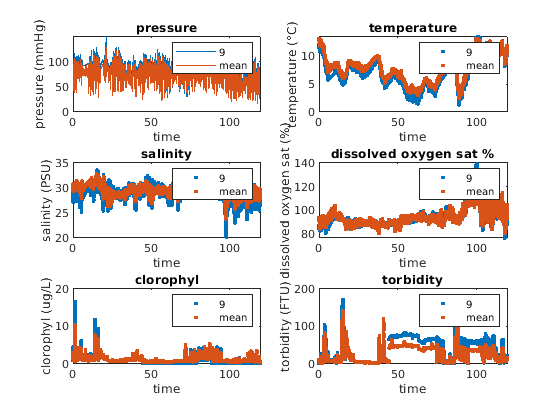

figure
subplot(3,2,1)
plot(SD.date_time, SD.pressure, '-', SDmean.date_time, SDmean.pressure,'-')
xlabel('time')
ylabel('pressure (mmHg)')
h1 = legend('9','mean');
title('pressure')
subplot(3,2,2)
plot(SD.date_time, SD.temperature, '.',SDmean.date_time, SDmean.temperature, '.')
xlabel('time')
ylabel('temperature (°C)')
h1 = legend('9','mean');
title('temperature')
subplot(3,2,3)
plot(SD.date_time, SD.salinity, '.',SDmean.date_time, SDmean.salinity, '.')
xlabel('time')
ylabel('salinity (PSU)')
h1 = legend('9','mean');
title('salinity')
subplot(3,2,4)
plot(SD.date_time, SD.dissolved_oxygen, '.',SDmean.date_time, SDmean.dissolved_oxygen, '.')
xlabel('time')
ylabel('dissolved oxygen sat (%)')
h1 = legend('9','mean');
title('dissolved oxygen sat %')
subplot(3,2,5)
plot(SD.date_time, SD.clorophyl, '.',SDmean.date_time, SDmean.clorophyl, '.')
xlabel('time')
ylabel('clorophyl (ug/L)')
h1 = legend('9','mean');
title('clorophyl')
subplot(3,2,6)
plot(SD.date_time, SD.torbidity, '.',SDmean.date_time, SDmean.torbidity, '.')
xlabel('time')
ylabel('torbidity (FTU)')
h1 = legend('9','mean');
title('torbidity')
savefig('avgSamanet.fig')

## Model Verification

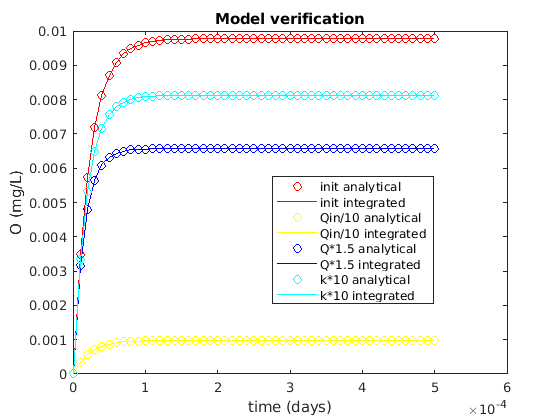

% Define some parameters
Qver = 864000000*60*1; % cm3 / day
Vver = 1*60*20000; %cm3
kver = 1000; %day^-1
Oinver = 10/1000;%mg/cm3
Qinver = Qver*Oinver; %mg/day
                                      
tspanver=[0:0.00001:0.0005]; % notice longer simulated period
O0ver = [0]; %IC for O md

%Y contains O (mg/l) for time TIME
[TIMEver, Yver1] = ode45(@(t,O) CSTR2_analytical(t,O,Qinver,Qver,kver,Vver),tspanver,O0ver); 
[TIMEver, Yver2] = ode45(@(t,O) CSTR2_analytical(t,O,Qinver/10,Qver,kver,Vver),tspanver,O0ver); 
[TIMEver, Yver3] = ode45(@(t,O) CSTR2_analytical(t,O,Qinver,Qver*1.5,kver,Vver),tspanver,O0ver); 
[TIMEver, Yver4] = ode45(@(t,O) CSTR2_analytical(t,O,Qinver,Qver,kver*10,Vver),tspanver,O0ver); 

% analytical solution
gamma1 = Qver/Vver+kver;
O_analytical1 = (1-exp(-gamma1.*tspanver))*Qinver /(gamma1*Vver);
gamma2 = Qver/Vver+kver;
O_analytical2 = (1-exp(-gamma2.*tspanver))*Qinver/10 /(gamma2*Vver);
gamma3 = Qver*1.5/Vver+kver;
O_analytical3 = (1-exp(-gamma3.*tspanver))*Qinver /(gamma3*Vver);
gamma4 = Qver/Vver+kver*10;
O_analytical4 = (1-exp(-gamma4.*tspanver))*Qinver /(gamma4*Vver);

figure
plot(tspanver,O_analytical1,'or',TIMEver,Yver1,'-r',tspanver,O_analytical2,'oy',TIMEver,Yver2,'-y',...
    tspanver,O_analytical3,'ob',TIMEver,Yver3,'-b',tspanver,O_analytical4,'oc',TIMEver,Yver4,'-c')
xlabel('time (days)')
ylabel('O (mg/L)')
h1 = legend('init analytical','init integrated','Qin/10 analytical','Qin/10 integrated','Q*1.5 analytical','Q*1.5 integrated','k*10 analytical','k*10 integrated');
title('Model verification')

legend('Position',[0.48631,0.2758,0.2875,0.30357])
savefig('verification.fig')

## Calibration

% ---- interpolations ----
global T
T = TK; % t [K]

global Cobs
Cobs = interp1(tobs, DOSD.dissolved_oxygen, tspan); % do [mg/L]

global h
h = interp1(tobs_h, TIDE.water_level, tspan)/100 + 0.60; % h (z) [m]

global v
dh = (TIDE.water_level(2:end)-TIDE.water_level(1:end-1))/100; % [m]
dt = days(TIDE.date_time(2:end)-TIDE.date_time(1:end-1)); % [days]
dhdt = dh./dt; % [m/days]
v = interp1(tobs_h(2:end), dhdt, tspan); % v [m/days]
clear dh dt dhdt

% mask for lowering tide
mask = v<0;

global R
R = interp1(tobs_R, RAH.radiation, tspan); %W/m2

global Osat
Osat = SDmean.osat; % [mg/L]

global A
A = SDmean.clorophyl; %ug Ch a/L

% -------------------------------------
% some computations outside the model function
%global ws
%ws = interp1(tobs_ws, 1+0.2395*WIND.wind.^1.643, tspan); % m/s

global Oin
Oin = Osat.*SDmean.dissolved_oxygen/100;
Oin(mask) = 0.0;

global Oout
Oout = zeros(length(Oin),1);
Oout(mask) = 1.0;

global vhi
vhi = v.*Oin.';

global vho
vho = v.*Oout.';

global vhv
vhv = - v./h;

Define some model parameters...

% -----------------------------------------
% BEST INITIAL ESTIMATES
% -----------------------------------------
kv = 0.9175; % adim
kl = 0.43; %days^-1
theta = 1.011;
Pmax = 19.46; %mgO2/mgCHl day
alpha = 0.283;
beta = 0.1905;
Ik = mean(RAH.radiation); %W/m^2
kr = 4.8; % mg O2/mg CHl day % directly proportional to peak height

% -----------------------------------------
% IC
% -----------------------------------------
O0 = 8.6711; % mg/L

Let's fit the model

% run model with initial estimates of parameters and compare it to data
opts = odeset('RelTol',1e-3);
[time, conc] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv,kl,theta,Ik,Pmax,alpha,beta,kr),tspan,O0,opts);

% velocità
[time_lin, conc_lin] = ode45(@(t,O) CSTR2in(t,O,kv),tspan,O0,opts);

% reareation
[time_rear, conc_rear] = ode45(@(t,O) reareation(t,O,kl,theta),tspan,O0,opts);

Error using interp1>reshapeAndSortXandV (line 447)
LENGTH(X) and SIZE(V,1) must be the same.

Error in interp1 (line 128)
    [X,V,orig_size_v] = reshapeAndSortXandV(X,V);

Error in reareation (<a href="matlab


% photo
[time_photo, conc_photo] = ode45(@(t,O) photo(t,O,Ik,Pmax,alpha,beta),tspan, O0,opts);

% respiration
[time_resp, conc_resp] = ode45(@(t,O) respiration(t,O,theta,kr),tspan, O0,opts);

...and see the results

figure
plot(tspan,Cobs,'-r',time,conc,'-b')
xlabel('time (days)')
ylabel('concentration')
h1 = legend('observations','model');
title('unfitted model')
savefig('unfitted.fig')

% %Nash Sutcliffe efficiency calculation
num = 0;
den = 0;
for jj=1:size(Cobs,2)
    num=num+(Cobs(1,jj)-interp1(time,conc,tspan(1,jj)))^2; % this is the sum of squared residuals between
                                                          % modelled values and observations  
    
    den=den+(Cobs(1,jj)-mean(Cobs(1,:)))^2; % this is the sum of squared residuals in which the "model"
                                            % is a horizontal line with intercept equal to the mean
                                            % of observations. Thus if EFF computed below is < 0 it means 
                                            % that num>den and your model performs in a worse manner than 
                                            % such line, thus your the model is not very useful.
end
EFF = 1 - num/den; % Nash Sutcliff efficiency
% 'end'
% 
% % How can you compare models with different complexities (no. of
% % parameters?). Is EFF good enough? The answer is no, you should use AICc (Akaike
% % Information Criterion corrected for finite sample size)
% % In the case of normal residuals, AICc can be computed as
% %
K = 1 + 9;%length(param_fitted);
N = length(Cobs);
AICc = 2*K + N*log(num/N) + 2*K*(K+1)/(N-K-1);

'The fitted model has efficiency'

ans = 'The fitted model has efficiency'

EFF

EFF = -0.3834

'and residual sum of squares'

ans = 'and residual sum of squares'

sqrt(num/N)

ans = 6.4598

'and AiCc'

ans = 'and AiCc'

AICc

AICc = 1.2803e+05

N

N = 34307

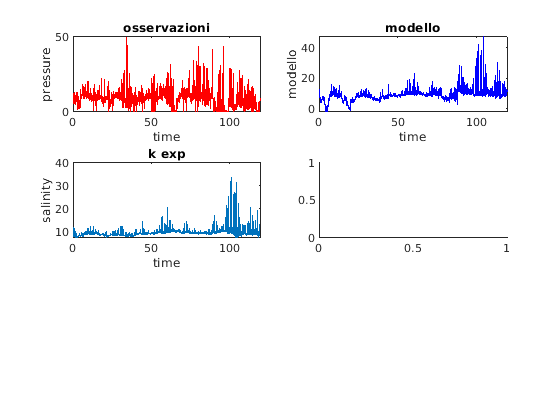


figure
subplot(3,2,1)
plot(tspan,Cobs,'-r')
xlabel('time')
ylabel('pressure')
title('osservazioni')
subplot(3,2,2)
plot(time,conc,'-b')
xlabel('time')
ylabel('modello')
title('modello')
subplot(3,2,3)
plot(time_lin, conc_lin)
xlabel('time')
ylabel('salinity')
title('k exp')
subplot(3,2,4)

plot(time_rear, conc_rear)

Unrecognized function or variable 'time_rear'.

xlabel('time')
ylabel('dissolved oxygen sat (%)')
title('reareation')
subplot(3,2,5)
plot(time_photo, conc_photo)
xlabel('time')
ylabel('clorophyl')
title('fotosintesi')
subplot(3,2,6)
plot(time_resp, conc_resp)
xlabel('time')
ylabel('torbidity')
title('respirazione')
savefig('allcontributions.fig')

Gridsearch!

%kl,theta,Ik,Pmax,alpha,beta,k_lin,kr
 kv_range = [0.01 5]; % adim
 kl_range = [0.1 1.1]; % d^-1
 theta_range = [1 1.08]; % adim
 Ik_range = [100 200];
 Pmax_range = [2 25];
 alpha_range = [0 1];
 kr_range = [2 20]; %mgO2/ugCHl day

 O0_range = [5 10]; %mg/L
 
 lb = [kv_range(1) kl_range(1) theta_range(1) Ik_range(1) Pmax_range(1) alpha_range(1) alpha_range(1) kr_range(1) O0_range(1)];%lower bounds 
 ub = [kv_range(2) kl_range(2) theta_range(2) Ik_range(2) Pmax_range(2) alpha_range(2) alpha_range(2) kr_range(2) O0_range(2)];%upper bounds
 
 param = [kv kl theta Ik Pmax alpha beta kr O0];


 options=optimoptions('lsqnonlin','display','iter-detailed','FiniteDifferenceStepSize',5e-2,'MaxFunEvals',100,'MaxIter',10,'Display','iter-detailed','TolX',1e-8);
 [param_fitted, resnorm] = lsqnonlin(@CSTR2residuals,param,lb,ub,options); % @residuals=parametri che minimizzano 


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0         10     1.43161e+06                      2.04e+06
     1         20     1.22717e+06       0.812488        1.1e+06      
     2         30     1.13708e+06        1.11552       2.06e+05      
     3         40     1.11191e+06       0.660918       1.67e+05      
     4         50     1.10003e+06       0.891985       1.13e+05      
     5         60     1.09659e+06       0.222996       3.42e+04      
     6         70     1.09659e+06       0.055749       3.42e+04      
     7         80     1.09627e+06      0.0139373       5.03e+05      
     8         90     1.09627e+06     0.00348432       5.03e+05      
     9        100     1.09489e+06    0.000871079       1.09e+05      
    10        110     1.09489e+06     0.00174216       1.09e+05      

Solver stopped prema

 kv_fit=param_fitted(1);
 kl_fit=param_fitted(2);
 theta_fit=param_fitted(3);
 Ik_fit=param_fitted(4);
 Pmax_fit=param_fitted(5);
 alpha_fit=param_fitted(6);
 beta_fit=param_fitted(7);
 kr_fit=param_fitted(8);
 O0_fit=param_fitted(9);
 
 [time2, conc2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);   

Let's see the results...

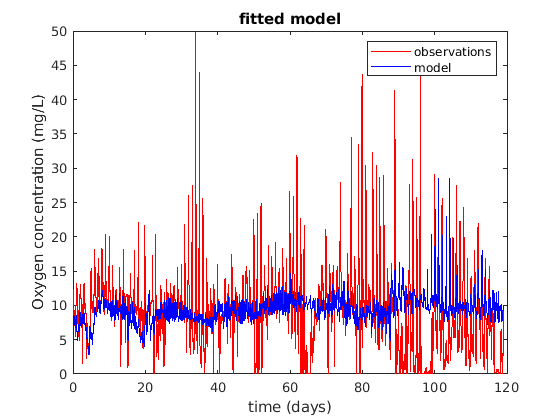


% plot fitting results 
figure
plot(tspan,Cobs,'-r',time2,conc2,'-b')
title('fitted model')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
h2 = legend('observations','model');
savefig('fitted.fig')

Efficiency calculation

% %Nash Sutcliffe efficiency calculation
num = 0;
den = 0;
for jj=1:size(Cobs,2)
    num=num+(Cobs(1,jj)-interp1(time2,conc2,tspan(1,jj)))^2; % this is the sum of squared residuals between
                                                          % modelled values and observations  
    
    den=den+(Cobs(1,jj)-mean(Cobs(1,:)))^2; % this is the sum of squared residuals in which the "model"
                                            % is a horizontal line with intercept equal to the mean
                                            % of observations. Thus if EFF computed below is < 0 it means 
                                            % that num>den and your model performs in a worse manner than 
                                            % such line, thus your the model is not very useful.
end
EFF = 1 - num/den; % Nash Sutcliff efficiency
% 'end'
% 
% % How can you compare models with different complexities (no. of
% % parameters?). Is EFF good enough? The answer is no, you should use AICc (Akaike
% % Information Criterion corrected for finite sample size)
% % In the case of normal residuals, AICc can be computed as
% %
K = 1 + length(param_fitted);
N = length(Cobs);
AICc = 2*K + N*log(num/N) + 2*K*(K+1)/(N-K-1); %AIC corrected for finite sample size
% %
% % where K is 1 + the number of fitted parameters of your model, N is the number of observations used for calibration, 
% % RSS is the residual sum of squares.
% % About this, you can read the book by Burnham & Anderson (2002), Model Selection and Multimodel Inference: A Practical
% % Information-Theoretic Approach (2nd ed.), Springer-Verlag


Results


% print results on screen
'fitted parameters are'

ans = 'fitted parameters are'

kv_fit

kv_fit = 1.4824

kl_fit

kl_fit = 0.8008

theta_fit

theta_fit = 1.0001

Ik_fit

Ik_fit = 147.0027

Pmax_fit

Pmax_fit = 14.0834

alpha_fit

alpha_fit = 0.5529

beta_fit

beta_fit = 0.1357

kr_fit

kr_fit = 2.9504

O0_fit

O0_fit = 8.3884

'The fitted model has efficiency'

ans = 'The fitted model has efficiency'

EFF

EFF = -0.0580

'and residual sum of squares'

ans = 'and residual sum of squares'

sqrt(num/N)

ans = 5.6493

'and AiCc'

ans = 'and AiCc'

AICc

AICc = 1.1883e+05

'nr of obs'

ans = 'nr of obs'

N

N = 34307

## MOSE

% -----------------------------------------
% read in the data of dissolved oxygen
% -----------------------------------------
filename = 'date_mose.txt';
varNames = {'up','down'};
varTypes = {'char','char'}; 
delimiter = '	';
extraColRule = 'ignore';
opts = delimitedTextImportOptions('VariableNames',varNames,...
                                'VariableTypes',varTypes,...
                                'Delimiter',delimiter,...
                                'MissingRule', 'omitrow',...
                                'ExtraColumnsRule',extraColRule); 
MOSE = readtable(filename,opts);

% CONVERT datetime columns
MOSE.up = days(datetime(MOSE.up, 'Inputformat', 'yyyy-MM-dd HH:mm:ss')-DOSD.date_time(1));
MOSE.down = days(datetime(MOSE.down, 'Inputformat', 'yyyy-MM-dd HH:mm:ss')-DOSD.date_time(1));


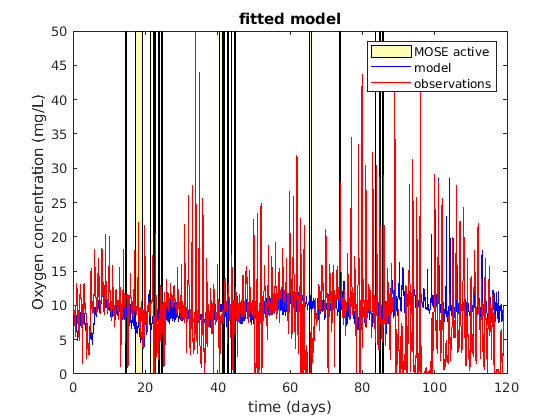


figure
plot(tspan,Cobs,'-r',time2,conc2,'-b')
title('fitted model')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
% Add lines
for j=1:length(MOSE.up)
    patch([MOSE.up(j) MOSE.down(j) MOSE.down(j) MOSE.up(j)],[0 0 50 50],'y')
    alpha(0.3);
end
% h1 = line([20 20],[0 50]);
% h2 = line([25 25],[0 50]);
% % Set properties of lines
% set([h1 h2],'Color','k')
% % Add a patch
% patch([20 25 25 20],[0 0 50 50],'y')
% alpha(0.3);
% % The order of the "children" of the plot determines which one appears on top.
% I need to flip it here.
set(gca,'children',flipud(get(gca,'children')))
h2 = legend('MOSE active','','','','','','','','','','','','','','','','model','observations');

%savefig('fitted.fig')

## Validation

Cobs_vali = [Cobs(1,round(length(Cobs)/2):round(length(Cobs)/2)+2016)];
tspan_vali = [tspan(1,round(length(tspan)/2):round(length(tspan)/2)+2016)];

[timev, concv] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan_vali,O0_fit);   


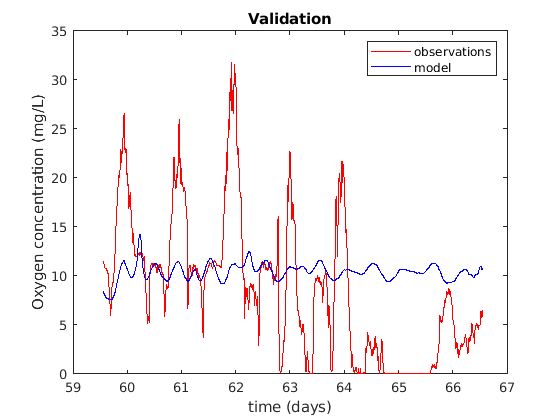


% plot fitting results 
figure
plot(tspan_vali,Cobs_vali,'-r',timev,concv,'-b')
title('Validation')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
h2 = legend('observations','model');
savefig('fitted.fig')

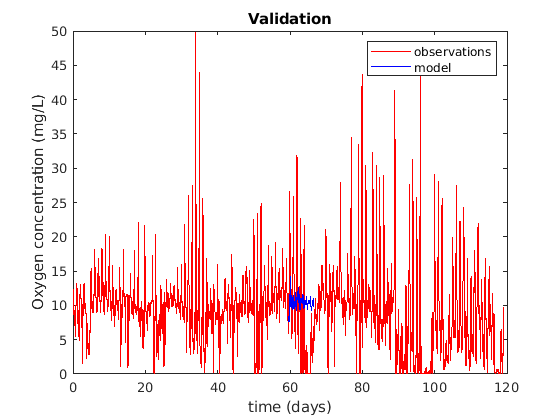

figure
plot(tspan,Cobs,'-r',timev,concv,'-b')
title('Validation')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
h2 = legend('observations','model');
savefig('fitted.fig')

num = 0;
den = 0;
for jj=1:size(Cobs_vali,2)
    num=num+(Cobs_vali(1,jj)-interp1(timev,concv,tspan_vali(1,jj)))^2; % this is the sum of squared residuals between
                                                          % modelled values and observations  
    
    den=den+(Cobs_vali(1,jj)-mean(Cobs_vali(1,:)))^2; % this is the sum of squared residuals in which the "model"
                                            % is a horizontal line with intercept equal to the mean
                                            % of observations. Thus if EFF computed below is < 0 it means 
                                            % that num>den and your model performs in a worse manner than 
                                            % such line, thus your the model is not very useful.
end
EFF = 1 - num/den;
K = 1 + length(param_fitted);
N = length(Cobs_vali);
AICc = 2*K + N*log(num/N) + 2*K*(K+1)/(N-K-1);

'The fitted model has efficiency'

ans = 'The fitted model has efficiency'

EFF

EFF = -0.0428

'and residual sum of squares'

ans = 'and residual sum of squares'

sqrt(num/N)

ans = 7.2960

'and AiCc'

ans = 'and AiCc'

AICc

AICc = 8.0370e+03

N

N = 2017

## Sensitivity Analysis

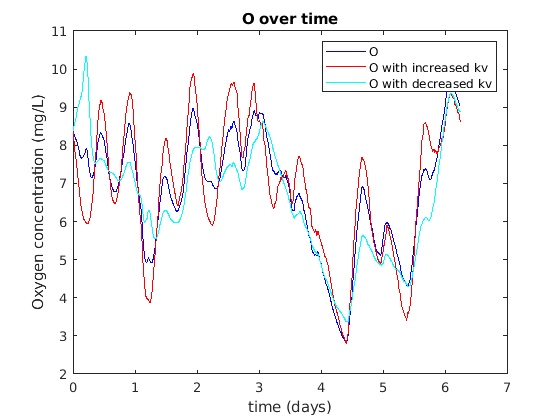

% ----------------------
% kv
%-----------------------
variat = 0.25; % for example 25% (è una variazione locale)  
kv_var = kv_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_var,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; % CN dconc/conc / dp/p il . è importante, se non lo mettiamo ci da errore
% try and decrease k (is the effect the same as in the case of increasing k?)
kv_var = kv_fit*(1-variat); %in questo caso abbasso del 25%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_var,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat; % CN

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased kv','O with decreased kv')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivitykv.fig')

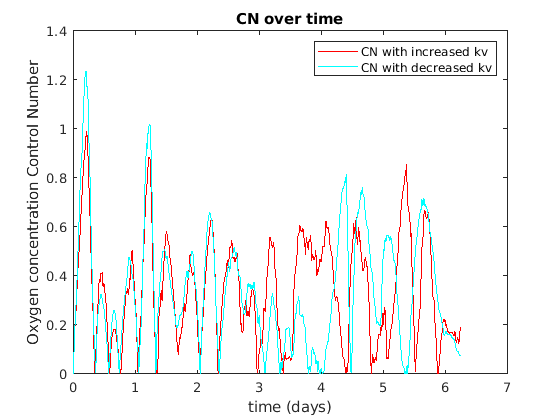


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c'); % ON over time incrementando k
title('CN over time')
legend('CN with increased kv','CN with decreased kv')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
savefig('sensitivityckv.fig')


CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.3144


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.3222

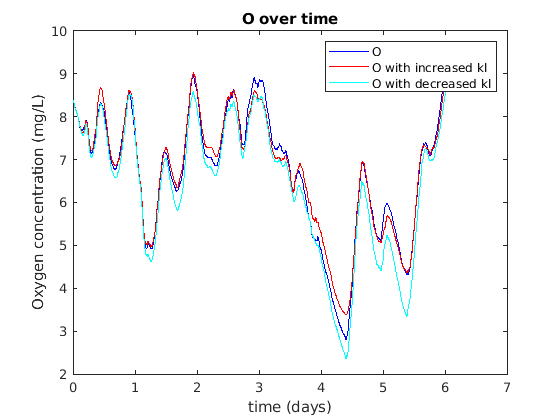

% -----------
% kl
% ----------
kl_var = kl_fit*(1+variat);
[time_20, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_var,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; % CN dconc/conc / dp/p il . è importante, se non lo mettiamo ci da errore
kl_var = kl_fit*(1-variat); %in questo caso abbasso del 5%;
[time_20, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_var,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time_20(1:1800),conc_var(1:1800),'r',time_20(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased kl','O with decreased kl')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivitykl.fig')

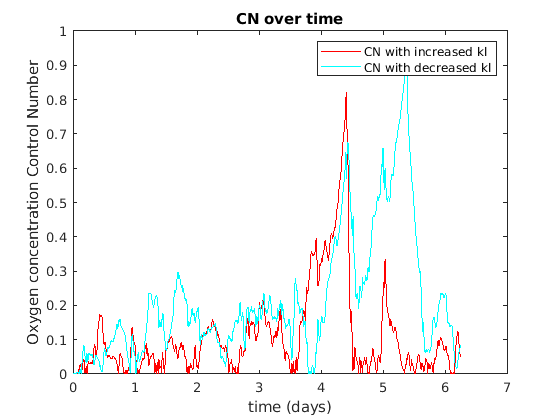


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased kl','CN with decreased kl')

savefig('sensitivityckl.fig')

CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.1176


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.1169

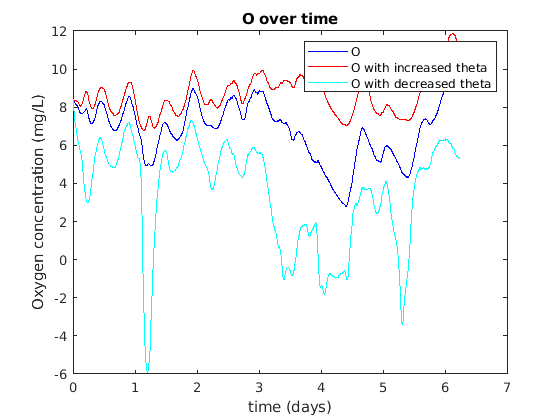

% ------
% theta
% ------
theta_var = theta_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_var,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; % CN dconc/conc / dp/p il . è importante, se non lo mettiamo ci da errore
theta_var = theta_fit*(1-variat); %in questo caso abbasso del 5%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_var,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased theta','O with decreased theta')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivitytheta.fig')

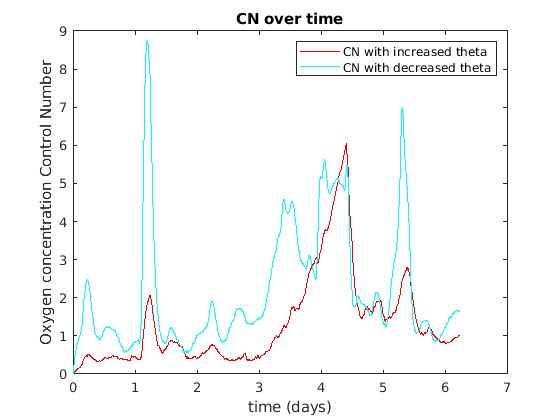


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased theta','CN with decreased theta')
savefig('sensitivityctheta.fig')


CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.9503


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 1.6067

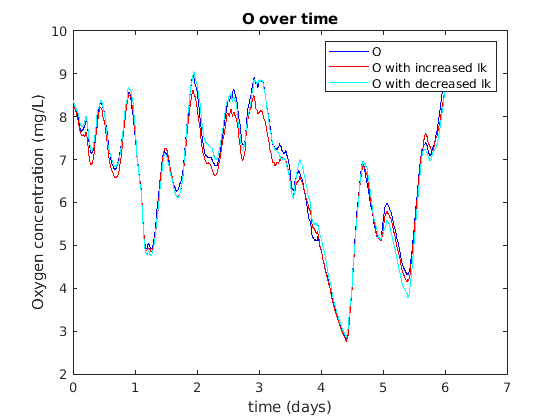

% ---
% Ik
% ---
Ik_var = Ik_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_var,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; 
Ik_var = Ik_fit*(1-variat); %in questo caso abbasso del 5%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_var,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased Ik','O with decreased Ik')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivityik.fig')

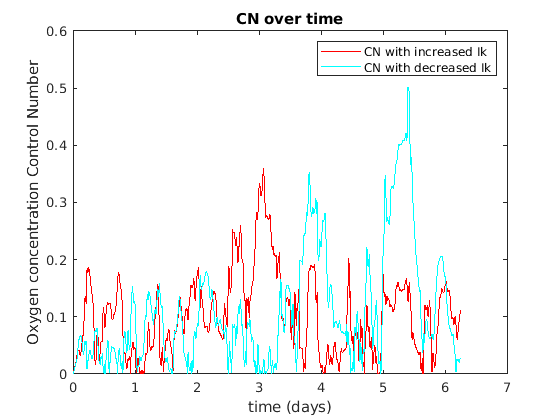


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased Ik','CN with decreased Ik')
savefig('sensitivitycik.fig')


CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.1116


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.1247

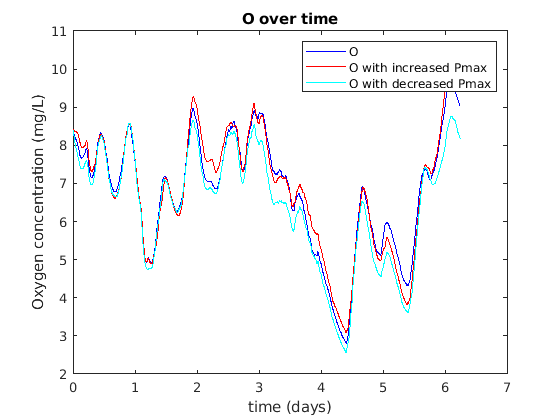

% -----
% Pmax
% -----
Pmax_var = Pmax_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_var,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; 
Pmax_var = Pmax_fit*(1-variat); %in questo caso abbasso del 5%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_var,alpha_fit,beta_fit,kr_fit),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased Pmax','O with decreased Pmax')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivityPmax.fig')

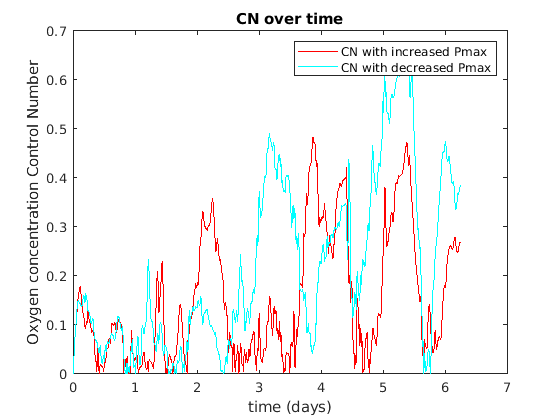


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased Pmax','CN with decreased Pmax')
savefig('sensitivitycPmax.fig')


CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.1766


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.1699

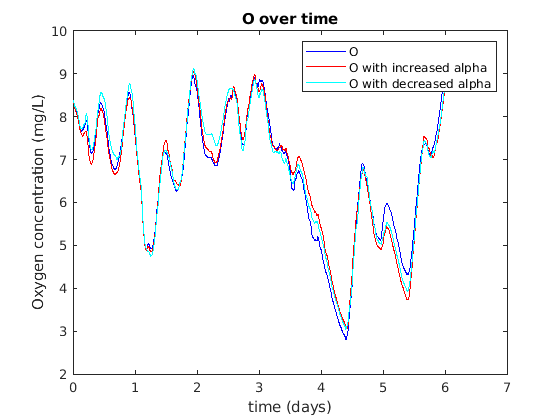

% ------
% alpha
% ------
alpha_var = alpha_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_var,beta_fit,kr_fit),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; 
alpha_var = alpha_fit*(1-variat); %in questo caso abbasso del 5%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_var,beta_fit,kr_fit),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased alpha','O with decreased alpha')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivityalpha.fig')

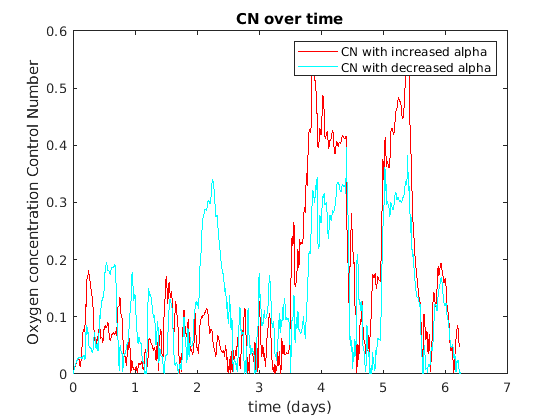


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased alpha','CN with decreased alpha')

savefig('sensitivitycalpha.fig')

CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.1112


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.1029

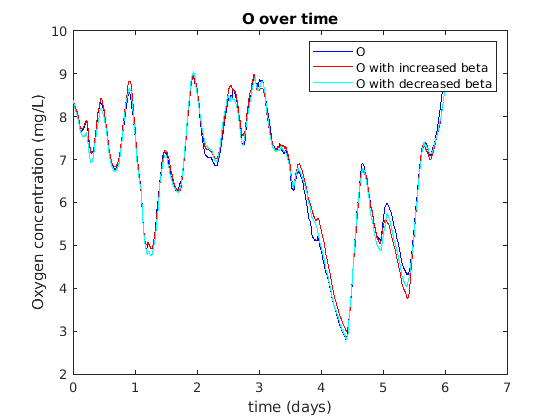

% -----
% beta
% -----
beta_var = beta_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_var,kr_fit),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; 
beta_var = beta_fit*(1-variat); %in questo caso abbasso del 5%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_var,kr_fit),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased beta','O with decreased beta')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivitybeta.fig')

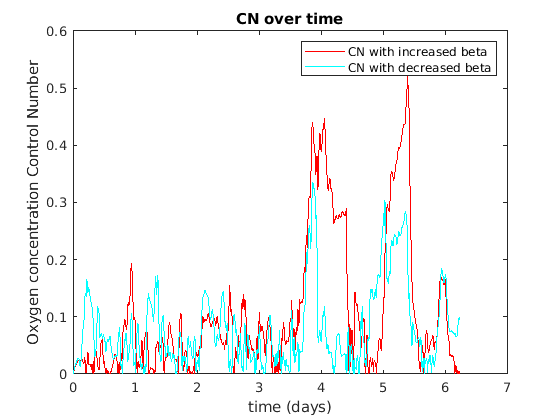


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased beta','CN with decreased beta')
savefig('sensitivitycbeta.fig')


CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.1026


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.1032

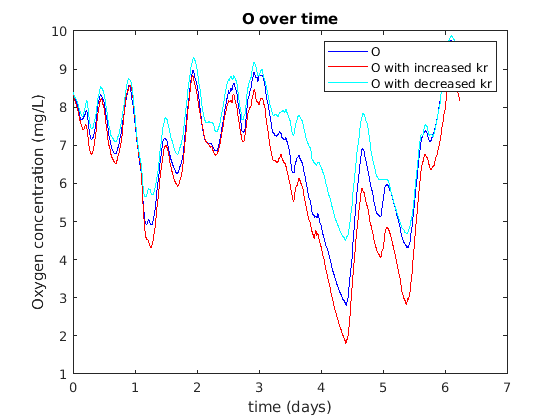

% ----
% kr
% ----
kr_var = kr_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_var),tspan,O0_fit);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; 
kr_var = kr_fit*(1-variat); %in questo caso abbasso del 5%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_var),tspan,O0_fit);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased kr','O with decreased kr')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivitykr.fig')

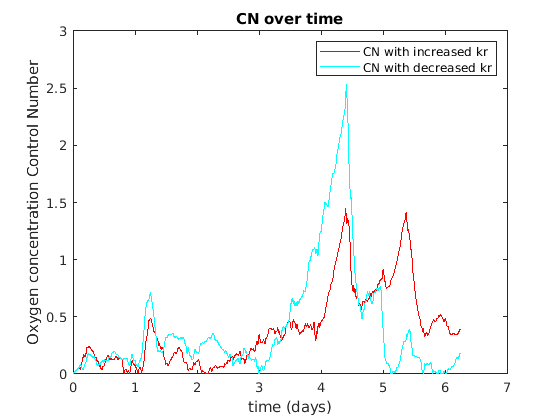


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased kr','CN with decreased kr')

savefig('sensitivityckr.fig')

CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.2052


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.2230

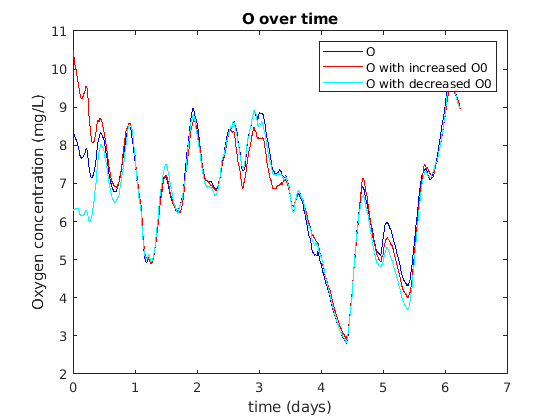

% ----
% O0
% ----
O0_var = O0_fit*(1+variat);
[time, conc_var] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_var);
dconc=abs(conc2-conc_var); % difference in concentration due to the change in k
CN_k_plus = dconc./conc2/variat; 
O0_var = O0_fit*(1-variat); %in questo caso abbasso del 5%;
[time, conc_var2] = ode45(@(t,O) CSTR2_fun_trial(t,O,kv_fit,kl_fit,theta_fit,Ik_fit,Pmax_fit,alpha_fit,beta_fit,kr_fit),tspan,O0_var);                           
dconc2=abs(conc2-conc_var2);
CN_k_minus = dconc2./conc2/variat;

figure
plot(time(1:1800),conc2(1:1800),'b',time(1:1800),conc_var(1:1800),'r',time(1:1800),conc_var2(1:1800),'c')
legend('O','O with increased O0','O with decreased O0')
title('O over time')
xlabel('time (days)')
ylabel('Oxygen concentration (mg/L)')
savefig('sensitivityo0.fig')

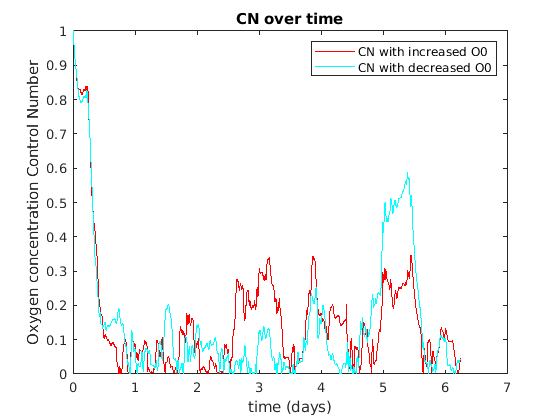


figure
plot(time(1:1800),CN_k_plus(1:1800),'r',time(1:1800),CN_k_minus(1:1800),'c');
title('CN over time')
xlabel('time (days)')
ylabel('Oxygen concentration Control Number')
legend('CN with increased O0','CN with decreased O0')
savefig('sensitivityco0.fig')


CN_avgplus = mean(CN_k_plus)

CN_avgplus = 0.1060


CN_avgminus = mean(CN_k_minus)

CN_avgminus = 0.0965